# Tracking a ballistic object on reentry

Reference: Beyond the Kalman Filter, B. Ristic, chapter 5

this simulation deals with tracking an object ( asteroid, satellite, missile... ) as it enters the Earth's atmosphere. Two simplifications: the radar's measurement model is not actually linear, and the asteroid is not likely to fall following a vertical trajectory, rather an angled one...

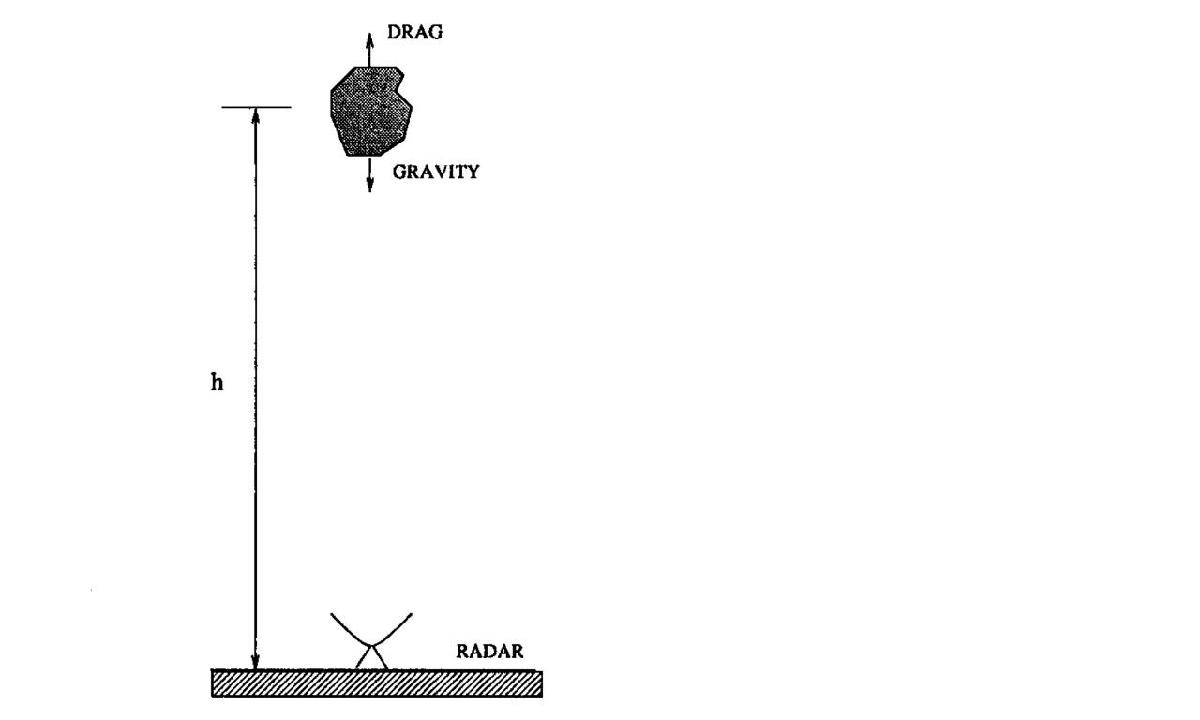

## Simulation parameters


N = 300;
x = zeros(3,N+1);

x(:,1) = [61e3 ; 3048; 19161];
tau = 0.1;
q1 = 0;
q2 = 0;
Q = [q1*tau*tau*tau/3, q1*tau*tau*0.5, 0;
     q1*tau*tau*0.5, q1*tau, 0;
     0 0 q2*tau];

y = zeros(1,N);
H = [1, 0, 0];
R = 200*200; % Sensor noise variance
T = tau; % Capital T is the sensor frequency



## Simulation


for i = 1 : N
    x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)';
    y(:,i) = H*x(:,i) + sqrt(R)*randn();
end
x

x = 1.0e+04 *

    6.1000    6.0695    6.0390    6.0085    5.9780    5.9475    5.9170    5.8864    5.8559    5.8253    5.7948    5.7642    5.7336    5.7030    5.6724    5.6418    5.6112    5.5806    5.5500    5.5193    5.4887    5.4580    5.4273    5.3966    5.3660    5.3353    5.3046    5.2739    5.2431    5.2124    5.1817    5.1509    5.1202    5.0894    5.0586    5.0279    4.9971    4.9663    4.9355    4.9047    4.8739    4.8431    4.8122    4.7814    4.7506    4.7197    4.6889    4.6580    4.6271    4.5963
    0.3048    0.3049    0.3050    0.3051    0.3052    0.3053    0.3054    0.3054    0.3055    0.3056    0.3057    0.3058    0.3059    0.3060    0.3061    0.3062    0.3063    0.3063    0.3064    0.3065    0.3066    0.3067    0.3068    0.3069    0.3070    0.3070    0.3071    0.3072    0.3073    0.3074    0.3074    0.3075    0.3076    0.3077    0.3078    0.3078    0.3079    0.3080    0.3081    0.3081    0.3082    0.3083    0.3083    0.3084    0.3085    0.3085    0.3086    0.3086    

y

y = 1.0e+04 *

    6.0977    6.0518    6.0467    6.0151    5.9991    5.9143    5.9182    5.8928    5.8402    5.8189    5.7978    5.7622    5.7155    5.7110    5.6743    5.6339    5.6071    5.5411    5.5329    5.5506    5.5093    5.4573    5.4375    5.3940    5.3564    5.3189    5.3128    5.2699    5.2561    5.2257    5.1872    5.1562    5.1314    5.1185    5.0510    5.0037    4.9955    4.9859    4.9450    4.9343    4.8533    4.8576    4.7656    4.7758    4.7215    4.6988    4.7199    4.6700    4.6504    4.5642


## Plot noiseless trajectory + noisy sensor measurements

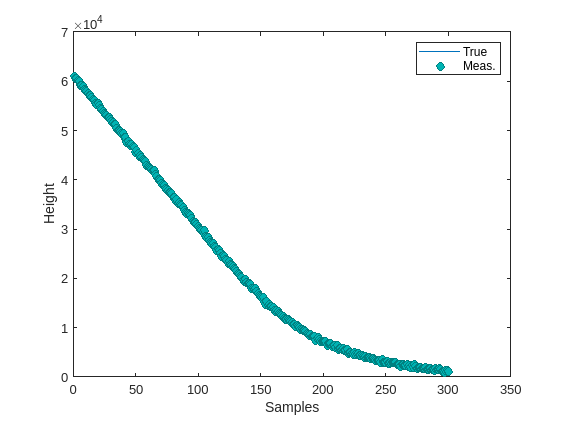


figure
plot(x(1,:))
xlabel("Samples")
ylabel("Height")
hold on;
scatter([1:1:N], y(1,:),'MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',0.2)
legend("True","Meas.")

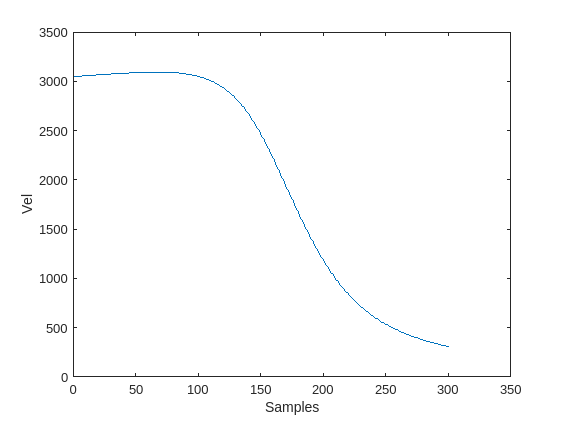


figure
plot(x(2,:))
xlabel("Samples")
ylabel("Vel")

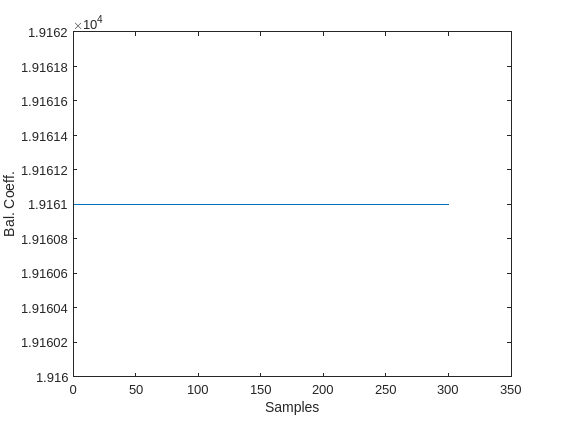


figure
plot(x(3,:))
xlabel("Samples")
ylabel("Bal. Coeff.")

## Initial variance of object


sigma_beta = 7184; % Variance of ballistic coeff.
P_0 = [R , R/tau , 0;
            R/tau , 2*R/(tau*tau) , 0;
            0 , 0 , sigma_beta*sigma_beta];


## CRLB (noiseless)

here we compute the Cramer Rao Lower Bound for the given samples

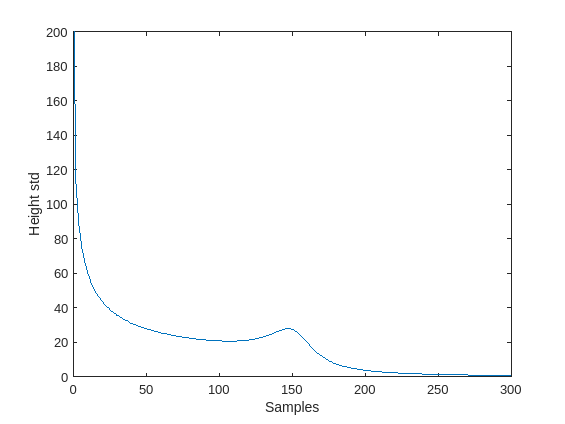

J = zeros(3,3,N);
J(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix
CRLB = zeros(3,3,N);
CRLB(:,:,1) = P_0;
cholCRLB = zeros(3,3,N);
cholCRLB(:,:,1) = chol(CRLB(:,:,1));

invR = inv(R);
g = 9.80665;
eta = 1.49e-4;

for i = 2 : N
    f21 = eta*g*p(x(1,i))*x(2,i)*x(2,i)/(2*x(3,i));
    f22 = g*p(x(1,i))*x(2,i)/x(3,i);
    f23 = g*p(x(1,i))*x(2,i)/(2*x(3,i)*x(3,i));
    Ftilde = [1, -tau, 0;
              f21*tau, 1-f22*tau, f23*tau;
              0, 0, 1];
    invFtilde = inv(Ftilde);
    J(:,:,i) = (H')*invR*H + (invFtilde')*J(:,:,i-1)*invFtilde;
    diagJ = diag(diag(J(:,:,i)));
    CRLB(:,:,i) = inv(diagJ);
    cholCRLB(:,:,i) = chol(CRLB(:,:,i));
end

% Now we plot the result


%plot. squeeze reshapes the vectors into columns rather than timeseries so i use transpose

figure
plot( squeeze(cholCRLB(1,1,:))' )
xlabel("Samples")
ylabel("Height std")

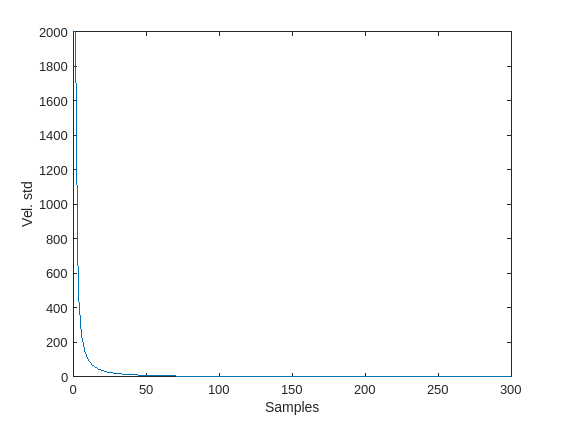


figure
plot( squeeze(cholCRLB(2,2,:))' )
xlabel("Samples")
ylabel("Vel. std")

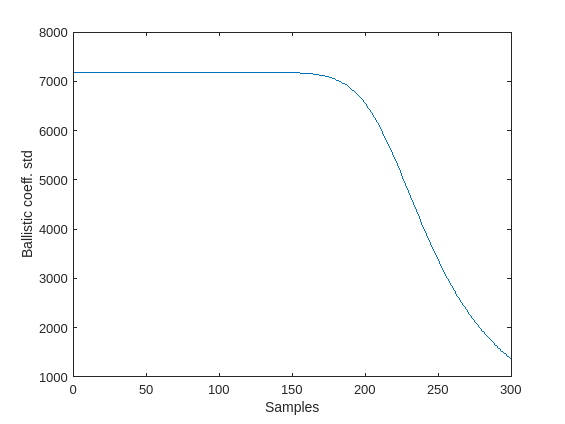


figure
plot( squeeze(cholCRLB(3,3,:))' )
xlabel("Samples")
ylabel("Ballistic coeff. std")

Remember that the CRLB constitutes a true lower bound only up to second order statistics. Neverthless, it's still a useful benchmark

#### CRLB (Noisy)

here we vary the process noise.

This is the recursion in the presence of process noise

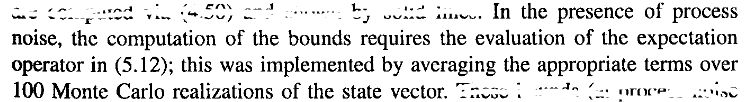

We wish to create two timeseries:

1)Matrix Timeseries of Ftilde over time. 

2)Matrix Timeseries of the product (Ftilde')QFtilde over time

q1 = 5;
q2 = 5; % Change the amount of noise
Q = [q1*tau*tau*tau/3, q1*tau*tau*0.5, 0;
     q1*tau*tau*0.5, q1*tau, 0;
     0 0 q2*tau];

x = zeros(3,N+1);
x(:,1) = [61e3 ; 3048; 19161];

M = 100; % This is the number of monte carlo runs
FtildeS = zeros(3,3,N,M);
FtinvQFS = zeros(3,3,N,M);


invQ = inv(Q);

for j = 1 : M
    x(:,1) = [61e3 ; 3048; 19161]; % Reset the initial condition
    for i = 1 : N
            f21 = eta*g*p(x(1,i))*x(2,i)*x(2,i)/(2*x(3,i));
            f22 = g*p(x(1,i))*x(2,i)/x(3,i);
            f23 = g*p(x(1,i))*x(2,i)/(2*x(3,i)*x(3,i));
            Ftilde = [ 1, -tau, 0;
                       f21*tau, 1-f22*tau, f23*tau;
                       0, 0, 1]; 
            FtildeS(:,:,i,j) = Ftilde;
            FtinvQFS(:,:,i,j) = (Ftilde')*invQ*Ftilde;
            x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)'; % Compute nxt variable
    end
end


% Now we have to compute the noisy CRLB. Take the same code we used before,
% but now we have precomputed the gradient

J = zeros(3,3,N);
J(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix

noiselessCholCRLB = cholCRLB; % Save noiselss result

CRLB = zeros(3,3,N);
CRLB(:,:,1) = P_0;
cholCRLB = zeros(3,3,N);
cholCRLB(:,:,1) = chol(CRLB(:,:,1));

% ev before the variable name stands for "expected value". We evaluate it
% in the following way:
% 1) First, consider the kth column of the 3rd dimension, that is where we have stored
% the evaluations related to the kth time for all the runs
% 2) Then, sum columnwise on the 4th dimension, that is the sample space,
% and average by M



    

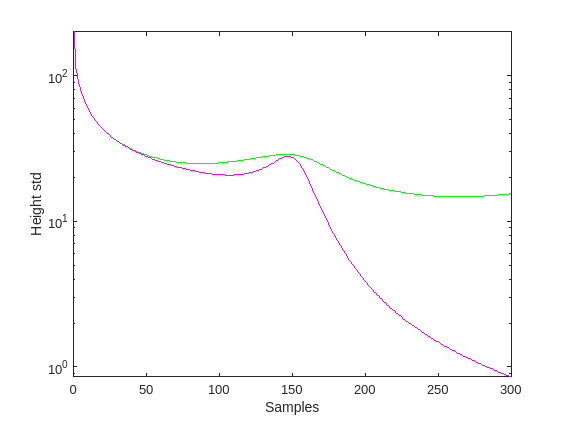

for k = 2 : N 
    %
      evFtilde = zeros(3,3);
      evFtinvQFS =  zeros(3,3); % Reset the sum
            for j = 1 : M
               evFtilde = evFtilde + FtildeS(:,:,k,j);
               evFtinvQFS =  evFtinvQFS + FtinvQFS(:,:,k,j) ;
            end
            evFtilde = evFtilde/M;
            evFtinvQFS = evFtinvQFS/M;
   %
    J(:,:,k) = invQ + (H')*invR*H - invQ*evFtilde*inv(evFtinvQFS + J(:,:,k-1) )*(evFtilde')*invQ; % This looks 
    diagJ = diag(diag(J(:,:,k)));
    CRLB(:,:,k) = inv(diagJ);
    cholCRLB(:,:,k) = chol(CRLB(:,:,k));
end


figure
semilogy( squeeze(cholCRLB(1,1,:))'  , "green")
xlabel("Samples")
ylabel("Height std")
hold on
semilogy( squeeze(noiselessCholCRLB(1,1,:))' , "magenta" )

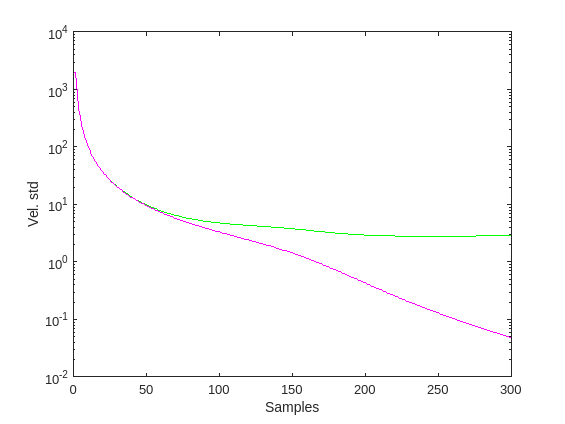



figure
semilogy( squeeze(cholCRLB(2,2,:))',"green")
xlabel("Samples")
ylabel("Vel. std")
hold on
semilogy( squeeze(noiselessCholCRLB(2,2,:))' , "magenta" )

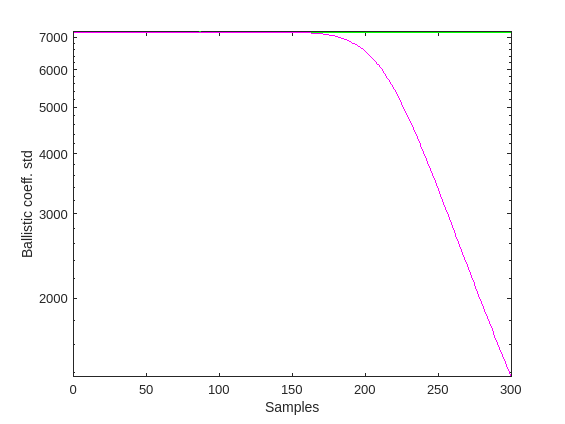


figure % This doesn't plot in log scale for some  reason ?????????
semilogy( squeeze(cholCRLB(3,3,:))', "green"  )
xlabel("Samples")
ylabel("Ballistic coeff. std")
hold on
semilogy( squeeze(noiselessCholCRLB(3,3,:))' ,  "magenta" )

# Estimation algorithms

Regenerate a (noisy) target state trajectory once more. Then we declare the covariance for whichever state estimate we might apply afterwards

x = zeros(3,N+1);
x(:,1) = [61e3 ; 3048; 19161];
q1 = 5;
q2 = 5; % Change the amount of noise
Q = [q1*tau*tau*tau/3, q1*tau*tau*0.5, 0;
     q1*tau*tau*0.5, q1*tau, 0;
     0 0 q2*tau];

for i = 1 : N
    x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)';
    y(:,i) = H*x(:,i) + sqrt(R)*randn();
end
x

x = 1.0e+04 *

    6.1000    6.0695    6.0390    6.0085    5.9780    5.9475    5.9170    5.8864    5.8559    5.8254    5.7948    5.7642    5.7337    5.7031    5.6725    5.6419    5.6113    5.5807    5.5501    5.5195    5.4889    5.4582    5.4276    5.3970    5.3663    5.3356    5.3049    5.2743    5.2436    5.2129    5.1822    5.1515    5.1208    5.0901    5.0593    5.0286    4.9979    4.9671    4.9364    4.9056    4.8748    4.8441    4.8133    4.7825    4.7517    4.7209    4.6901    4.6593    4.6284    4.5976
    0.3048    0.3049    0.3050    0.3051    0.3052    0.3052    0.3053    0.3054    0.3055    0.3055    0.3057    0.3057    0.3058    0.3059    0.3060    0.3061    0.3060    0.3060    0.3062    0.3062    0.3063    0.3063    0.3065    0.3066    0.3067    0.3068    0.3068    0.3068    0.3067    0.3068    0.3070    0.3072    0.3073    0.3073    0.3073    0.3074    0.3075    0.3076    0.3076    0.3078    0.3077    0.3076    0.3078    0.3080    0.3080    0.3082    0.3083    0.3084    

y

y = 1.0e+04 *

    6.1216    6.0907    6.0187    6.0206    5.9260    5.9337    5.9342    5.8784    5.8567    5.8517    5.7833    5.7486    5.7410    5.7032    5.6651    5.6118    5.6191    5.5715    5.5407    5.5005    5.4817    5.4407    5.4335    5.3784    5.3839    5.3312    5.3300    5.2984    5.2160    5.1985    5.2065    5.1018    5.1140    5.1221    5.0487    5.0151    4.9949    4.9819    4.9199    4.9085    4.8727    4.8600    4.8379    4.8086    4.7416    4.6998    4.6784    4.6556    4.6616    4.5718


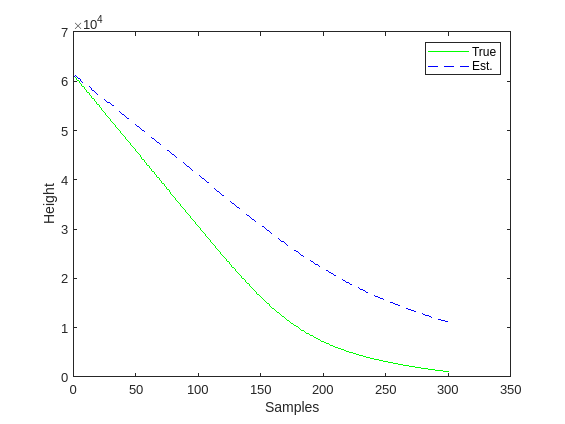


P = zeros(3,3,N+1);
P(:,:,1) = P_0;


x_hat = zeros(3,N+1);
x_hat(:,1) = x(:,1);
kappa = 0;
for i = 1 : N
   [ x_hat(:,i+1) , P(:,:,i+1) ] = myukf( x_hat(:,i) , P(:,:,i) , 0 , Q, y(:,i) , R, kappa);
end

% Plot the results
figure
plot(x(1,:), "Color","g")
xlabel("Samples")
ylabel("Height")
hold on;
plot(x_hat(1,:),"LineStyle","--","Color","b")
legend("True","Est.")

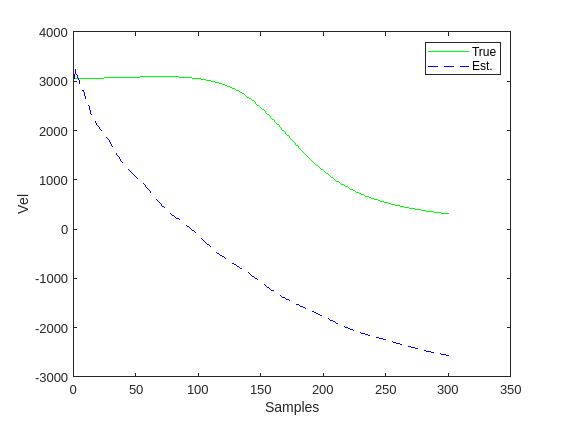


figure
plot(x(2,:), "Color","g")
xlabel("Samples")
ylabel("Vel")
hold on;
plot(x_hat(2,:),"LineStyle","--","Color","b")
legend("True","Est.")

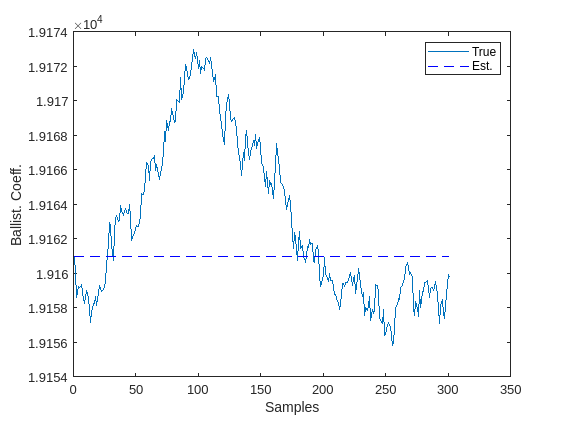


figure
plot(x(3,:))
xlabel("Samples")
ylabel("Ballist. Coeff.")
hold on;
plot(x_hat(3,:),"LineStyle","--","Color","b")
legend("True","Est.")

## Est. the information matrix from the UKF

Functions

function [p_out] = p(h_in)
gamma = 1.754;
eta = 1.49e-4;
p_out = gamma*exp(-eta*h_in);
end
    
function [x_nxt] = f(x,tau)
%Constants
g = 9.80665;

h = x(1);
v = x(2);
beta = x(3);

p_h = p(h);

h_dot = -v;
v_dot = -(p_h*g*v*v)/(2*beta) + g;
beta_dot = 0;

x_nxt =  x + tau*[h_dot ; v_dot; beta_dot];

end
